# **ACTIVIDAD 3. Evaluación - Parte 1**

Jesús Alejandro Gómez Bautista | A01736171

# 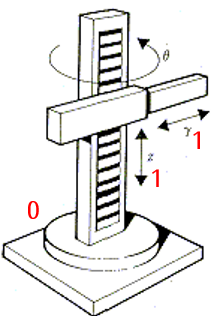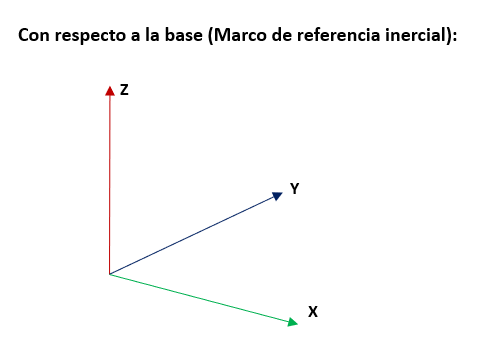

*Definiendo el marco de referencia incercial: *Considere el anterior marco de referencia a partir de la base rotacional de nuestra base, la cual en su centro parten las demás articulaciones del robot de tipo lineal, considere ideal, a partir de la regla de ubicación z, darle a z la misma dirección que la primera longitud a la vez que la rotación de su base es en el mismo eje. 

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) l1 l2(t) t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l1, l2];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%% Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1) = [cos(th1) -sin(th1) 0; % Análisis de robot péndulo
            sin(th1)  cos(th1) 0;
            0         0        1];

%% Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; l2 ; 0];
%Matriz de rotación de la junta 2 respecto a 1  -90º x
R(:,:,2)= [1  0  0;
           0  1  0;
           0  0  1];

%% Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ;0];
%Matriz de rotación de la junta 3 respecto a 2   
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];



%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,  0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0,  0 |
|                                  |
|      0,            0,      1, l1 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T2


/ cos(th1(t)), -sin(th1(t)), 0, -sin(th1(t)) l2(t) \
|                                                  |
| sin(th1(t)),  cos(th1(t)), 0,  cos(th1(t)) l2(t) |
|                                                  |
|      0,            0,      1,         l1         |
|                                                  |
\      0,            0,      0,          1         /



Matriz de Transformación global T3


/ cos(th1(t)), -sin(th1(t)), 0, -sin(th1(t)) l2(t) \
|                                                  |
| sin(th1(t)),  cos(th1(t)), 0,  cos(th1(t)) l2(t) |
|                                                  |
|      0,            0,      1,         l1         |
|                                                  |
\      0,            0,      0,          1         /





%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   _________                   \
|    d                          |
| - -- th1(t) cos(th1(t)) l2(t) |
|   dt                          |
|                               |
|   _________                   |
|    d                          |
| - -- th1(t) sin(th1(t)) l2(t) |
|   dt                          |
|                               |
|            ________           |
|             d                 |
|            -- l2(t)           |
\            dt                 /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



*Análisis de resultados: *

La matriz proporcionada como velocidad lineal se refiere al cambio en la posición a lo largo de una trayectoria recta, al existir interacciones entre lo largo y el angulo de la base, estas influeyen en los movimientos en x, y y z, auqnue puedan existir velocidades lineales, recordemos que en las angulares hay interacciones que en función de la junta existen o no.

En cuanto a la velocidad angular, hace sentido que la única que tenga un valor diferente de 0 sea aquella junta que fue definida como rotacional a diferencia del resto que son de tipo lineal, de ahí que esta velocidad angular en z dependa del ángulo de dicha junta, theta.